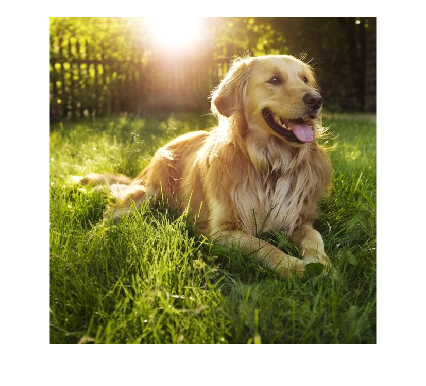

img = imread("squaredog.jpg");
imshow(img);

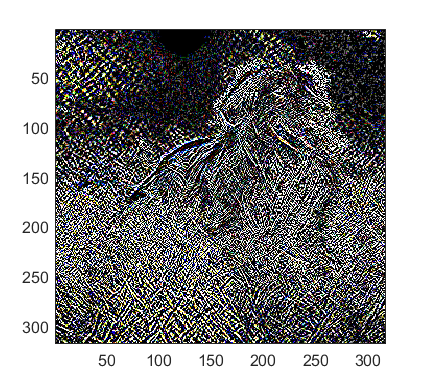

img = imresize(img,[634,634]);


[a,h,v,d] = haart2(img);



for i = 1:4
    d{i} = imgaussfilt3(d{i},.5);
    v{i} = imgaussfilt3(v{i},.5);
    h{i} = imgaussfilt3(h{i},.5);
end

imagesc(d{1})

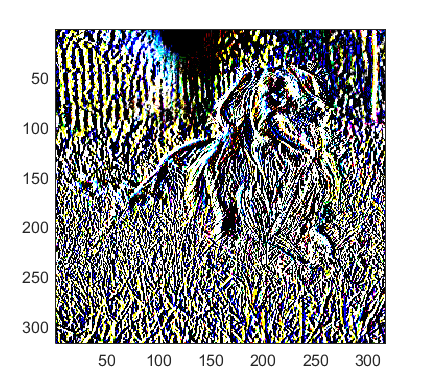

imagesc(v{1})

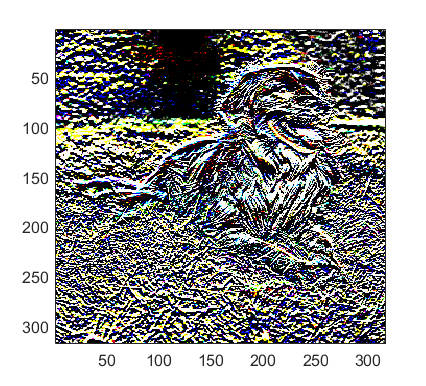

imagesc(h{1})

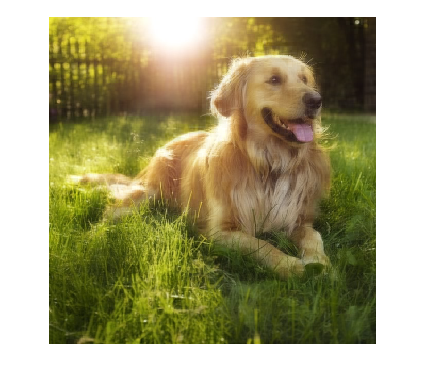



img = ihaart2(a,h,v,d);
imshow(uint8(img));